# Segundo Examen Parcial

# Primavera 2023

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 2 antes de las 11:25 horas. 

Cada pregunta vale 5 puntos.

**Aseguráte de que tus resultados se despliegan en el archivo que subas.**

**Las funciones al final del script no deben estar comentadas.**

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. Copiar el código de otra persona se considera plagio.

Recuerda salvar frecuentemente tu archivo.

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

## Pregunta 1.

a) Demuestra que la ecuación iterativa que define el método de Gauss Seidel para resolver un sistema de ecuacione $A\;x=b\;$es:


$$x_{k+1} =C+Tx_k$$


donde $T=-{\left(D+L\right)}^{-1} \;U$ es la matriz de iteración y $A=D+L+U$.

Pega aquí tu respuesta:

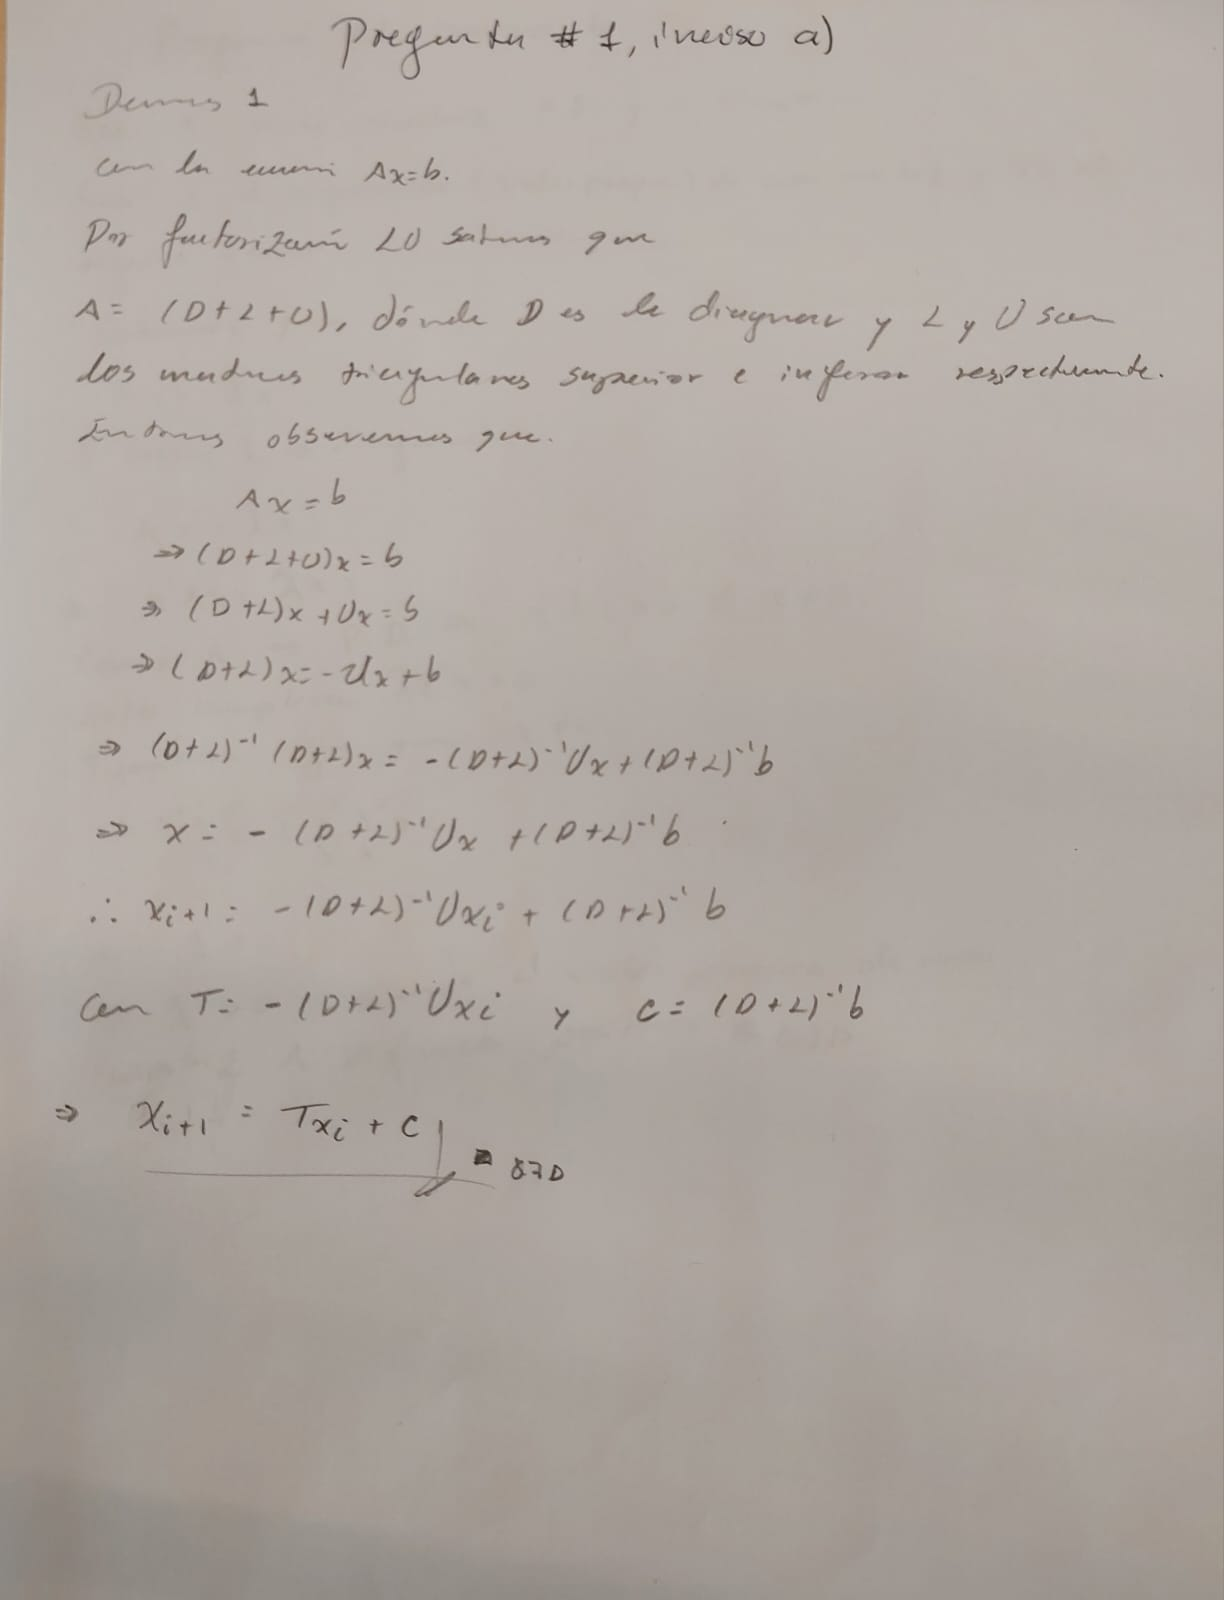

b) Demuestra que si $\lambda$ es un valor propio de una matriz$A$ definida positiva ($x^{\prime } A\;x>0\;\;\forall x\not= 0$) entonces $\lambda$>0.

Pega aquí tu respuesta:

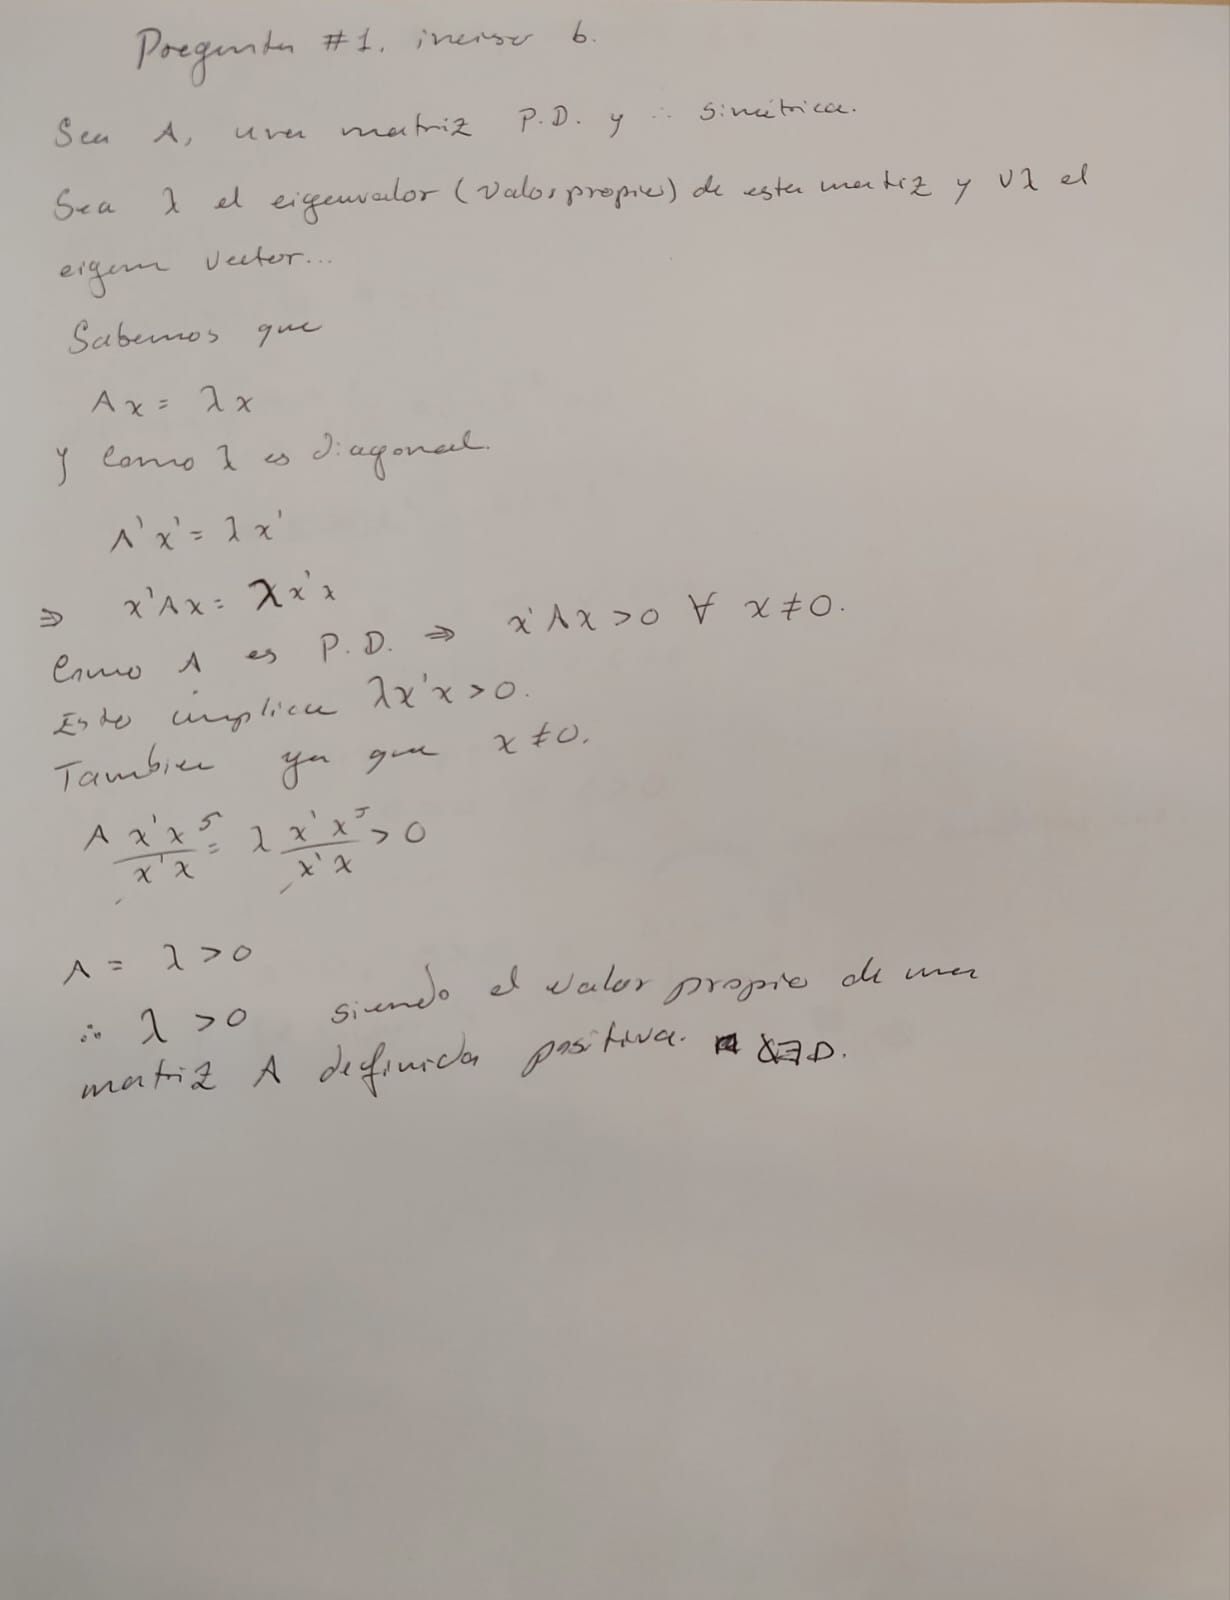

c) Demuestra que el criterio de Sylvester debe cumplirse para matrices (simétricas) definidas positivas de 2x2.


$$A=\left\lbrack \begin{array}{cc}
a & b\\
b & c
\end{array}\right\rbrack$$


Criterio de Sylvester

Todas las matrices siguientes tienen determinantes positivos:

- la superior izquierda de A de dimensión 1x1

- la superior izquierda de A de dimensión 2x2 (A en sí misma)

Pega aquí tu respuesta:

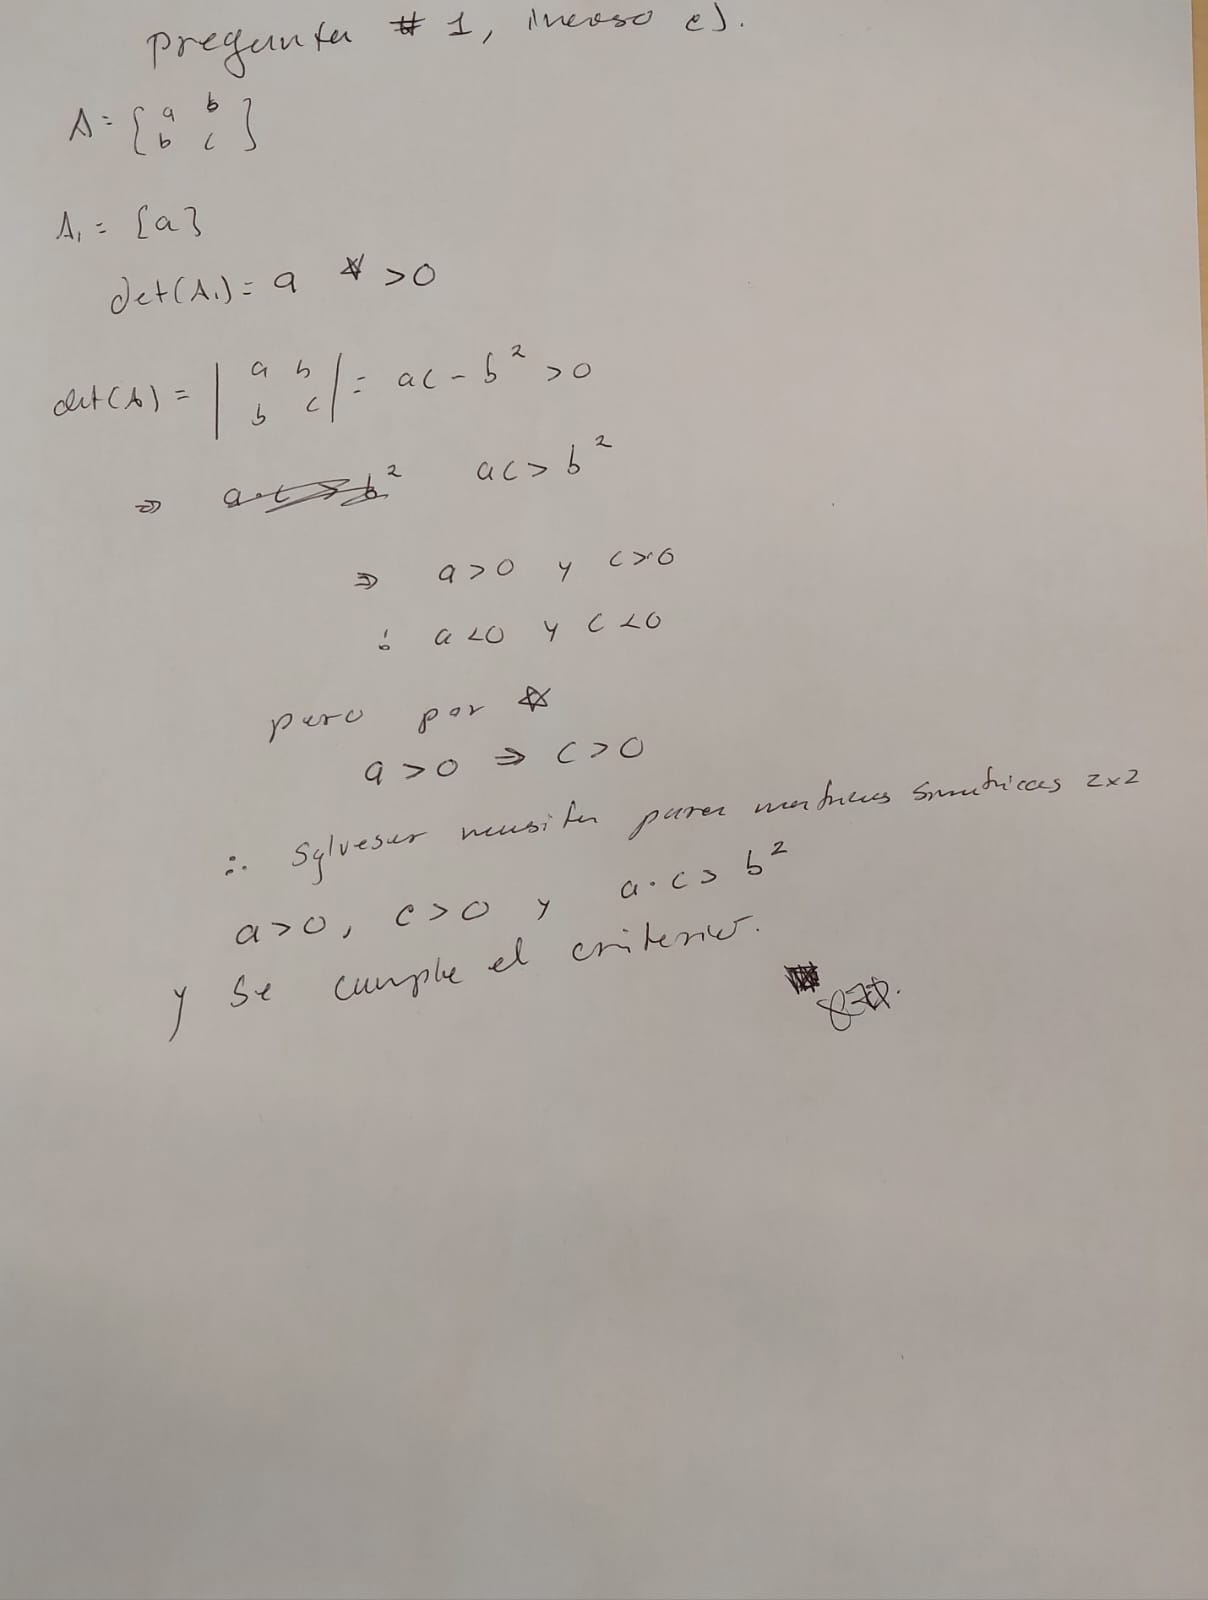

## Pregunta 2.

El método de sobre-relajación sucesiva (SOR) es una variante del método de Gauss-Seidel para estimar la solución de un sistema ecuaciones lineales, que puede permitir una convergencia más rápida. En cada iteración, despúes de calcular el nuevo valor de $x$, se substituye este valor por un promedio ponderado de los resultados de la iteración previa y la actual: 


$$x_{i+1} =\omega x_{i+1} +\left(1-\omega \right)x_i$$


where $\omega$ is a weighting factor between 1 and 2.

Programa, abajo en la sección de funciones, el método SOR y úsalo para resolver el siguiente sistema de ecuaciones $A\;x=b$:


$$\left\lbrack \begin{array}{cccc}
10 & -1 & 2 & 0\\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
6\\
25\\
-11\\
15
\end{array}\right\rbrack$$


A = [10,-1,2,0; -1,11,-1,3; 2,-1,10,-1; 0,3,-1,8]
b = [6;25;-11;15]

Primero, muestra en una línea de código que el método converge (diagonal estrictamente dominante). 

all(2*abs(diag(A)) > sum(abs(A),2))

Resuelve ahora el sistema usando el método SOR y $w=1\ldotp 05$. Utiliza una tolerancia relativa de $0\ldotp 5\times {10}^{-5}$.

 ¿En cuántas iteraciones converge?

rtol = 0.5e-5;
w = 1.05;
x = zeros(4,1);
[x, i] = SOR(A,b,w, rtol,x)
%Converge en 7 iteraciones.

## Pregunta 3.

Muestra, en una línea, que la matriz $A$ de la pregunta 2 es definida positiva (es simétrica y todos sus valores propios son positivos)

issymmetric(A) && all(eig(A)>0)

Como la matriz $A$ es definida positiva,  resuelve el sistema de ecuaciones del problema 3 usando el método del gradiente conjugado. ¿En cuántas iteraciones converge?

x = zeros(4,1);
[x,i]=Par2_gradienteConjugado(A, b, x)
%Converge en 4 iteraciones.

## Pregunta 4.

Programa, abajo en la sección de funciones, el método *cholesky* y úsalo para resolver el sistema de ecuaciones de la pregunta 2.

Encuentra la factorización de Cholesky.

L = funCholesky(A)

Comprueba que $A=L\;L^{\prime }$, donde $L$ es una matriz triangular inferior (y $L^{\prime }$es triangular superior).

AAux = L*L'
A
%Son Iguales

Resuelve el sistema  usando  L y los métodos *backsub* y *forsub* (debes modificar tu método forsub dado que $L$ no tiene unos en la diagonal). 

y = forsub(L,b)
x = Par2_backsub(L',y)
linsolve(A,b)

## Pregunta 5.

Utiliza el método de Newton-Raphson para resolver el siguiente sistema de ecuaciones no lineales:


$$3x_1 -\cos \left(x_2 x_3 \right)=\frac{3}{2}$$



$$4x_1^2 -625x_2^2 +2x_2 =1$$



$$e^{-x_1 x_2 } +20x_3 =-\frac{10\pi -3}{3}$$


Utiliza como primera aproximación [0; 1; 0].

syms x y z
xs = [x;y;z]
f1 = 3*x - cos(y*z) - 3/2;
f2 = 4*x^2 - 625*y^2 + 2*y -1;
f3 = exp(-x*y)+20*z -(10*pi - 3)/3;
fs = [f1;f2;f3]
Js = jacobian(fs, xs)
f = matlabFunction(fs, 'Vars', {xs})
J = matlabFunction(Js, 'Vars', {xs})
x0 = [0; 1; 0]; 
[x,i] = Par2_newtonRaphsonVV(f, J, x0)

## Escribe aquí tus funciones

### SOR

function [x,i] = SOR(A,b, omega,rtol,x0)
     D = diag(diag((A)));
     U = triu(A,1);
     L = tril(A,-1);
     T = -(D+L)\U;
     c = (D+L)\b;
     itmax = 52;
     x = x0;
     i = 1;
     cond = true;

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


     while cond

b =      6
    25
   -11
    15


         xp = x;
         x = T*xp+c;

ans = logical
   1


         x = omega*x + (1-omega)*xp;
         i = i+1;
         cond = (norm((x-xp)/x, Inf)) >rtol && i<itmax;
     end
end

### Gradiente conjugado

function [x,i] = Par2_gradienteConjugado(A,b,x)

x =     1.0000
    2.0000
   -1.0000
    1.0000


i = 7

    max = length(b);
    i = 1;
    tol = eps;
    r = b-A*x;
    d = r;

ans = logical
   1


    a = dot(r,r)/(d'*A*d);
    x = x+a*d;
    cond = true;

x =     1.0000
    2.0000
   -1.0000
    1.0000


i = 4

    while cond
        xp = x;
        rp = r;
        r = b - A*xp;
        d = r + dot(r,r)/dot(rp,rp)*d;
        a = dot(r,r)/(d'*A*d);

L =     3.1623         0         0         0
   -0.3162    3.3015         0         0
    0.6325   -0.2423    3.0889         0
         0    0.9087   -0.2525    2.6666


        x = xp+a*d;
        i = i+1;

AAux =    10.0000   -1.0000    2.0000         0
   -1.0000   11.0000   -1.0000    3.0000
    2.0000   -1.0000   10.0000   -1.0000
         0    3.0000   -1.0000    8.0000


        cond = norm((x-xp)./x, "Inf") > tol && i < max && any(r~=0);

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


    end
end

### Factorización o descomposición de Cholesky.

Toma su nombre del matemático André-Louis Cholesky, quien encontró que una matriz simétrica definida positiva puede ser descompuesta como el producto de una matriz triangular inferior*** L*** (con elementos positivos en la diagonal) y su traspuesta (Wikipedia).

Codifica aquí, de manera **estructurada** y **eficiente**, la función L=cholesky(A) que utiliza el algoritmo de Cholesky-Crout para calcular ***L*** columna por columna, iniciando en la esquina superior izquierda.

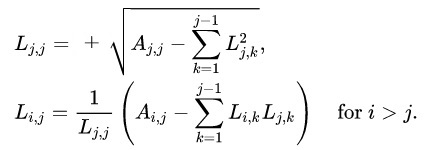

function L = funCholesky(A)

y =     1.8974
    7.7540
   -3.3414
    2.6666


    [n,~] = size(A);

x =     1.0000
    2.0000
   -1.0000
    1.0000


    L = zeros(n);

ans =     1.0000
    2.0000
   -1.0000
    1.0000


    for j = 1:n 
        sum = 0;
        for k=1:j 
            sum = sum + L(j,k)*L(j,k);
        end
        L(j,j) = sqrt(A(j,j) - sum);
        for i = j+1:n 
            sum = 0;
            for k=1:j

$$xs = \left(\begin{array}{c} x\\ y\\ z \end{array}\right)$$

                sum = sum + L(i,k) * L(j,k);
            end
            L(i,j) = 1 / L(j,j) * (A(i,j) - sum);
        end

$$fs = \left(\begin{array}{c} 3\,x-\cos\left(y\,z\right)-\frac{3}{2}\\ 4\,x^{2}-625\,y^{2}+2\,y-1\\ 20\,z+{\mathrm{e}}^{-x\,y}-\frac{5332248173269055}{562949953421312} \end{array}\right)$$

    end

$$Js = \left(\begin{array}{ccc} 3 & z\,\sin\left(y\,z\right) & y\,\sin\left(y\,z\right)\\ 8\,x & 2-1250\,y & 0\\ -y\,{\mathrm{e}}^{-x\,y} & -x\,{\mathrm{e}}^{-x\,y} & 20 \end{array}\right)$$

end

f = function_handle with value:
    @(in1)[in1(1,:).*3.0-cos(in1(2,:).*in1(3,:))-3.0./2.0;in1(2,:).*2.0+in1(1,:).^2.*4.0-in1(2,:).^2.*6.25e+2-1.0;in1(3,:).*2.0e+1+exp(-in1(1,:).*in1(2,:))-9.471975511965978]


### forsub (modificada para Cholesky)

function y = forsub(L,b)

J = function_handle with value:
    @(in1)reshape([3.0,in1(1,:).*8.0,-in1(2,:).*exp(-in1(1,:).*in1(2,:)),in1(3,:).*sin(in1(2,:).*in1(3,:)),in1(2,:).*-1.25e+3+2.0,-in1(1,:).*exp(-in1(1,:).*in1(2,:)),in1(2,:).*sin(in1(2,:).*in1(3,:)),0.0,2.0e+1],[3,3])


    n = length(b);
    y = zeros(size(b));

x =     0.8332
    0.0549
    0.4258


i = 8

    y(1,:) = b(1,:)/L(1,1);
    for i = 2:n
        y(i,:) = (b(i,:)-L(i, 1:i-1)*y(1:i-1,:))/L(i,i);
    end
end

### backsub

function x = Par2_backsub(U,b)
    n = length(b);
    x = zeros(size(b));
    x(n,:) = b(n,:)/U(n,n);
    for i = n-1:-1:1
        x(i,:) = (b(i,:)-U(i, i+1:end)*x(i+1:end,:))/U(i,i);
    end
end

### Newton-Raphson de varias variables

function [x,i] = Par2_newtonRaphsonVV(f,J,x)
    max = 520;
    tol = 1e-5;
    cond =  true;
    i=0;
    while cond
        xp = x;
        x = xp-J(xp)\f(xp);    
        i = i+1;
        cond = norm((x-xp)./x, "Inf") > tol && i < max;
    end
end